# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Postać kanoniczna układu równań liniowych

Do zobrazowania postaci kanonicznej posłużymy się toolboxem MATLABA Symbolic Toolbox, który realizuje obliczenia algebraiczne (nie numeryczne) wg reguł składniowych. 

clear all;
% Najpierw zdefiniujemy które zmienne MATLABA będą interpretowane jako
% zmienne symboliczne
syms x y z;                         %u nas będą to przy zmienne i układu równań 3x3

% Zdefiniujmy trzy przykładowe równania:


$$\left\lbrace \begin{array}{l}
2x+y+z=2\\
-x+y-z=3\\
x+2y+3z=-10
\end{array}\right.$$


row1 =  2*x + y + z == 2;
row2 = -x + y - z == 3;
row3 = x + 2*y + 3*z == -10;

% Pod zmienną row(x) kryje się teraz obiekt opisuący równanie np.
row1

$$row1 = 2\,x+y+z=2$$


% Możemy wydać MATLABOWI komendę przekształcenia takiego układu równań do postaci
% kanonicznej
[A,b] = equationsToMatrix([row1, row2, row3], [x, y, z]);

% W efekcie otrzymamy macierz A i wektor b kanonicznej postaci układu
% równań

A

$$A = \left(\begin{array}{ccc} 2 & 1 & 1\\ -1 & 1 & -1\\ 1 & 2 & 3 \end{array}\right)$$

b

$$b = \left(\begin{array}{c} 2\\ 3\\ -10 \end{array}\right)$$


% Taki układ równań możemy rozwiązać (jest to jednak rozwiązanie już
% numeryczne na podstawie postaci kanonicznej) w toolboxie:

x = linsolve(A,b)

$$x = \left(\begin{array}{c} 3\\ 1\\ -5 \end{array}\right)$$

Spróbujmy przyjrzeć się przedstawionemu przykładowi:

*Punkt w przestrzeni możemy potraktować jako system współrzędnych. Zgodnie z logiką stosowania macierzy obrót punktu wokół osi OY układu współrzędnych o kąt Θmożna opisać macierzą:*

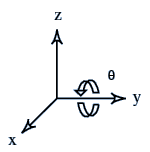


$$A=\left\lbrack \begin{array}{ccc}
\textrm{𝑐𝑜𝑠}\left(\textrm{𝜃}\right) & 0 & -\textrm{𝑠𝑖𝑛}\left(\textrm{𝜃}\right)\\
0 & 1 & 0\\
\textrm{𝑠𝑖𝑛}\left(\textrm{𝜃}\right) & 0 & \textrm{𝑐𝑜𝑠}\left(\textrm{𝜃}\right)
\end{array}\right\rbrack$$


Spróbujmy przeprowadzić analizę tego przykładu. Powiedzmy, że nasze znane położenie punktu po obrocie to [1,1,1], nasz problem zapisujemy tak:


$$\left\lbrack \begin{array}{ccc}
\textrm{𝑐𝑜𝑠}\left(\textrm{𝜃}\right) & 0 & -\textrm{𝑠𝑖𝑛}\left(\textrm{𝜃}\right)\\
0 & 1 & 0\\
\textrm{𝑠𝑖𝑛}\left(\textrm{𝜃}\right) & 0 & \textrm{𝑐𝑜𝑠}\left(\textrm{𝜃}\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack$$


co odpowiada takiemu układowi równań:


$$\left\lbrace \begin{array}{l}
\cos \left(\theta \right)x-\sin \left(\theta \right)z=1\\
y=1\\
\sin \left(\theta \right)\;x+\cos \left(\theta \right)z=1
\end{array}\right.$$


% Wprowadźmy o (theta) jako oznazenie kąta
syms o;

% Nasza macierz układu równań może być zapisana symbolicznie:
A = [cosd(o) 0 -sind(o);...
     0      1     0  ;...
     sind(o) 0  cosd(o)];
b=[1;1;1];

% Przyjmijmy, że o = 60 stopni (pi/3 radianów)
Asub = subs(A,o,60);

% Rozwiążmy taki układ:
x_symbolic = linsolve(A,b)

$$x\_symbolic = \left(\begin{array}{c} \frac{\cos\left(0.0175\,o\right)-\sin\left(0.0175\,o\right)}{{\cos\left(0.0175\,o\right)}^{2}+{\sin\left(0.0175\,o\right)}^{2}}\\ 1\\ \frac{\cos\left(0.0175\,o\right)+\sin\left(0.0175\,o\right)}{{\cos\left(0.0175\,o\right)}^{2}+{\sin\left(0.0175\,o\right)}^{2}} \end{array}\right)$$

x_numeric = linsolve(Asub,b)

$$x\_numeric = \left(\begin{array}{c} -0.3660\\ 1\\ 1.3660 \end{array}\right)$$

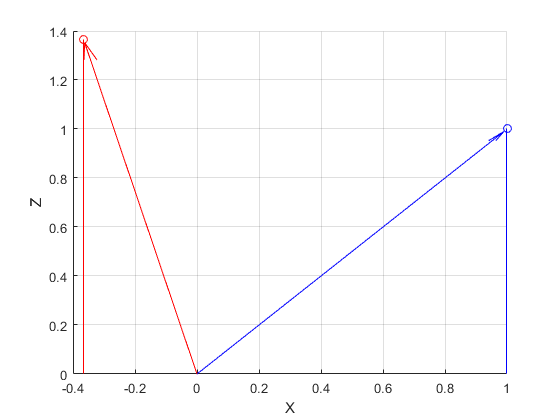

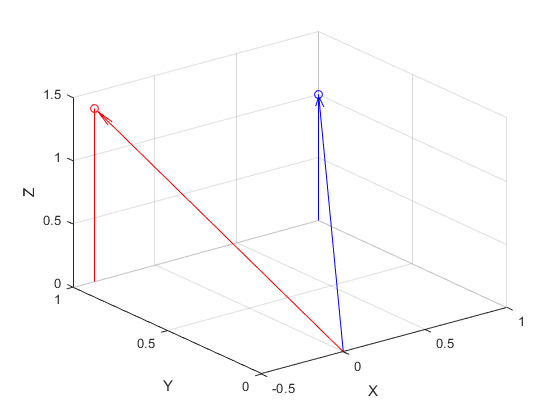


% Wyrysujmy oba punktu
rysujPunkty3D(x_numeric, b);

Spróbuj pozmieniać kąty obrotu. Zwróć uwagę, że w przypadku takigo zadania zmianie ulegnie wyłącznie macierz ***A***, ale nie wektor ***b***. Z takim przypadkiem mamy często do czynienia.

## **ZADANIE**

Uzupełnij poniższy skrypt wpisując postać macierzy ***A ***i wektora ***b*** dla poniższych przykładów tak, aby oddawała ona przedstawione poniżej układy równań, których rozwiązaniem są wektory samych jedynek:

a)


$$\left\lbrace \begin{array}{l}
3a-b+14c=16\\
a+2b+3c=6\\
a-12b-18c=-29
\end{array}\right.$$


b)


$$\left\lbrace \begin{array}{l}
5s=4t+1\\
r-11s+t=s-10\\
3r+s+3-7t=0
\end{array}\right.$$


%Tutaj wpisz swoją implementację macierzy

A=[];

b=[];

%Rozwiązanie układu równiań

x=A\b;

%Sprawdzenie czy OK:
if( (norm(x-ones(3,1))<1e-9) & isvector(x) & ~isempty(A) & ~isempty(b))
    fprintf("Bardzo dobrze!")
else
    fprintf("Spróbuj jeszcze raz...")
end

Bardzo dobrze!

## Wykorzystywane funkcje

function rysujPunkty3D(symbolicPoint, numericPoint) 
    
    %konwersja zmiennej symbolicznej do numerycznej 
    localNumeric1 = double(symbolicPoint);
    localNumeric2 = double(numericPoint);
    
    %Rysowanie 3D
    stem3(localNumeric1(1),localNumeric1(2),localNumeric1(3),'ro');hold on;
    stem3(localNumeric2(1),localNumeric2(2),localNumeric2(3),'bo');hold on;
    grid on;
    xlabel('X');ylabel('Y');zlabel('Z');view(0,0);
    quiver3(0,0,0,1.1*localNumeric2(1),1.1*localNumeric2(2),1.1*localNumeric2(3),'b');hold on;
    quiver3(0,0,0,1.1*localNumeric1(1),1.1*localNumeric1(2),1.1*localNumeric1(3),'r');hold off;
    
    %W 3D
    figure()
    
    %Rysowanie 3D
    stem3(localNumeric1(1),localNumeric1(2),localNumeric1(3),'ro');hold on;
    stem3(localNumeric2(1),localNumeric2(2),localNumeric2(3),'bo');hold on;
    grid on;
    xlabel('X');ylabel('Y');zlabel('Z');
    quiver3(0,0,0,1.1*localNumeric2(1),1.1*localNumeric2(2),1.1*localNumeric2(3),'b');hold on;
    quiver3(0,0,0,1.1*localNumeric1(1),1.1*localNumeric1(2),1.1*localNumeric1(3),'r');hold off;
    
end